## Part3 - Analyzing real data

So far, we have done a lot of work on simluated data. We know how to:

- Preprocess the spike times into a spike count matrix;

- Create a Support Vector Machine classifier;

- Compute a surrogates distribution for this classifier.

Now, let's try to apply those tools to real data.

### The organization of the real data

We are going to use data from a similar task. A head-fixed mouse was trained to differentiate between 2 sound stimuli. For each trial, one of the two stimulus would be played for 2 seconds (stimulus period) and then, after a 1-sec-window of silence (we call this the trace period), the animal would receive or not a reward (reward period), depending on wich sound was played. Because the stimuli and the reward periods do not overlap, we call this a trace-conditioning task. 

So now, in order to see the full extension of a trial, we are going to extract spikes from 1 second before the stimulus start (pre-stimulus period), to 4 seconds after it (2 s of stim, 1 s of trace and 1 s of reward periods).

### Loading the data

We first load the data, that is organized in the same way as our simulated data. 

clear all
load('real_data_example','spktimes','srate','stim_times','stim_type')


### Question 5

Redo the plot in question 4 using the real data. 

(Although this seems a long question, you should be able to reuse most of the code so far. However, remeber that the duration of the trials is different now, and that might require some modifications in the code..)

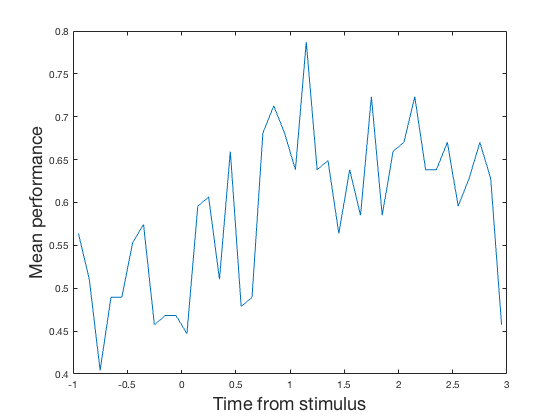

binwidth = 0.1; % in seconds (100 ms)
bins = 0:binwidth*srate:4*srate;
bins=bins/srate;

n_cells=length(spktimes);
n_trials= length(stim_type);

spk_matrix = zeros(n_cells,n_trials,length(bins)-1);
for icell = 1:length(spktimes)
    
    spk = spktimes{icell};
    
    for itrial = 1:length(stim_times)
        idx = (spk>stim_times(itrial)-1 & spk<=stim_times(itrial)+3);
        
        spk_temp = spk(idx)-(stim_times(itrial)-1);
        
        count = histc(spk_temp,bins);
        
        % the last count is for values higher than the last bin edge, so we can discard it.
        count = count(1:end-1);
        
        spk_matrix(icell,itrial, :) = count;
        
    end
end

% let's define our time vector as the center of each bin
time_bins = bins(1:end-1)+binwidth/2;

% we also want the time 0 to be the moment of the stimulus
time_bins = time_bins -1;


% setting the 2-fold crossvalidation
k=2;
% creating 2 disjoints sets
C = cvpartition(n_trials,'KFold',k);
bin_len = size(spk_matrix,3);
mean_performance = zeros(bin_len,1);
for bin=1:bin_len
    performance = zeros(k);
    for i=1:k
        % geting the training and test sets for the ith fold.
        trainingset = C.training(i);
        testset = C.test(i);
        
        % separating the activity of our bin of interest
        bin_matrix = squeeze(spk_matrix(:,:,bin));
        % creating the SVM model with the training data
        SVMModel = fitcsvm(bin_matrix(:,trainingset)',stim_type(trainingset),'KernelFunction','linear','Standardize',false);
        
        % predicting the test data with the model
        [predicted_type,score] = predict(SVMModel,bin_matrix(:,testset)');
                                    
        performance(i) = mean(predicted_type==stim_type(testset)');
    end
    mean_perf = mean(performance);
    mean_performance(bin) = mean_perf(1);
end



clf
new_performance = (mean_performance-mean(mean_performance))/std(mean_performance);
plot(time_bins,mean_performance)
xlabel('Time from stimulus','FontSize',18)
ylabel('Mean performance','FontSize',18)

### Question 6

Coment on the result you found on question 5. What can you conclude from the decoding performance on each period (pre-stimulus, stimulus, trace and reward)? What do you think of the decoding performance of the trace period? Did you expect that? 

Before the stimulus there is already some performance, but after the stimulus this really starts. In the trace period the performance goes up and down, but the reward really gives a peak. I did not expect that the trace period had such a big variance. 

### Bonus Question

Now that you know how to apply a surrogate/shuffling to analyze the statistical significance of a result, go back to assignment 1 and think of a way of doing this with the spatial information metric that you used there (Skagg's formula). What would be the best way to shuffle the data in order to compute each surrogate?

You can describe how you would do it here, or actually implement it (in python or matlab).